# DtFT

z zadania 1

f1 = 125

f1 = 125

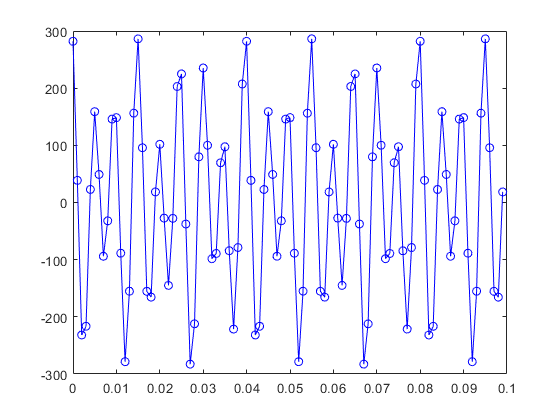

N = 100;


Agen = @(k,n) (1/sqrt(N))*(exp(1i*(2*pi)/N))^(-k*n);

A = zeros(N);
for n=1:N
    for k=1:N
        A(n,k)=Agen(n,k);
    end
end

fgen = @(t) 100*cos(2*pi*f1*t+pi/7) +  200*cos(2*pi*200*t+pi/11);


fs1000Hz = 1000;
x = fgen(0:1/fs1000Hz:(1/fs1000Hz*(N-1)));

clf
figure
plot(0:1/fs1000Hz:(1/fs1000Hz*(N-1)), x, 'b-o');


X = A*x';

x_after = (A')*X;

Docelowa czesc zadania

X1 = X;
M = 100;

xz = [x, zeros(1,M)];

X2 = fft(xz)./(N+M);

#### Obliczanie DtFT

f=-2000:0.25:2000-0.25;

f=0:0.25:1000-0.25;


X3 = zeros(1,length(f));

for itF=1:length(f)
    for itn=0:N-1
        X3(itF) = X3(itF) + x(itn+1)*exp(-1i*2*pi*f(itF)*itn/fs1000Hz);
    end
    % X3(itF) = X3(itF)/N;
end
X3 = X3./N;

Prezentacja danych

fx1 = 1000*(0:N-1)/N;
fx2 = 1000*(0:N+M-1)/(N+M);
fx3 = 1000*(0:length(X3)-1)/length(X3);

clf
figure
plot(fx1,X1,'o',fx2,X2,'bx',fx3,X3,'k-')

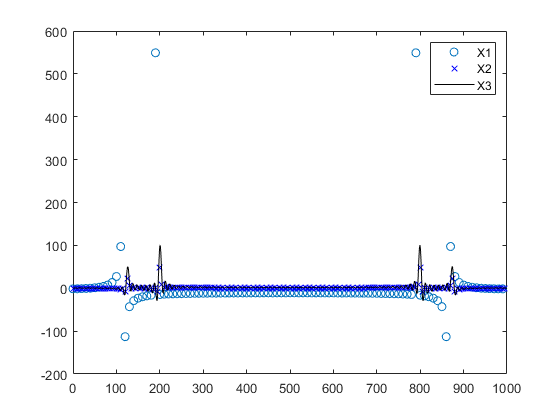

legend({"X1","X2","X3"})

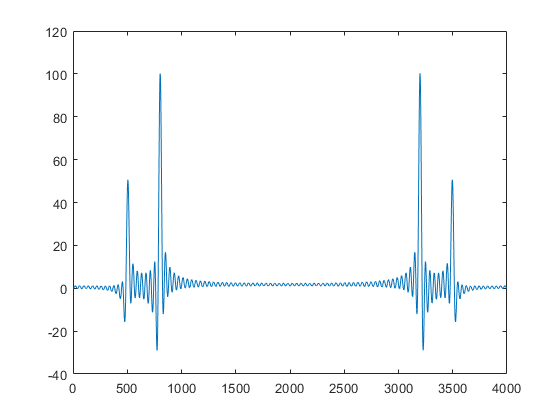



clf
figure
plot(real(X3))